clear
clf

load uspsDigits.mat;

noll = matToVec(0);
ett = matToVec(1);
tva = matToVec(2);
tre = matToVec(3);
fyra = matToVec(4);
fem = matToVec(5);
sex = matToVec(6);
sju = matToVec(7);
atta = matToVec(8);
nio = matToVec(9);

d = 10w; % dim ändra till vad som helst upp till 256

base0 = base(d,noll);
base1 = base(d,ett);
base2 = base(d,tva);
base3 = base(d,tre);
base4 = base(d,fyra);
base5 = base(d,fem);
base6 = base(d,sex);
base7 = base(d,sju);
base8 = base(d,atta);
base9 = base(d,nio);

% Skapa en array med testdatan

x = [];

for i=1:2007
    x = [x reshape(testDigits(:,:,i),[],1)];
end

% Skapa en variabel xDummy som i for loopen tar in en handskriven siffra i
% taget och skickas in i funktionen normRes
% results blir ifylld med de värdena som returneras av normRes en efter en

xDummy = 0;
results = zeros(1,2007);

for i=1:2007
    xDummy = x(:,i);
    results(1,i) = normRes(xDummy,d,noll,ett,tva,tre,fyra,fem,sex,sju,atta,nio,base0,base1,base2,base3,base4,base5,base6,base7,base8,base9);
end

% printar ut algoritmens resultat och facit(transponerad för bättre
% utseende)
results

results =      9     6     3     6     6     0     0     0     6     9     6     2     3     8     0     3     1     2     9     6     2     2     4     9     6     2     0     3     8     3     7     0     5     0     7     9     5     0     0     7     0     8     1     0     7     1     0     4     3     0


testAns'

ans =      9     6     3     6     6     0     0     0     6     9     6     2     2     4     0     3     1     6     9     6     2     2     4     9     6     2     0     3     8     3     7     0     5     0     7     9     5     0     0     7     0     8     1     0     7     1     0     4     2     0


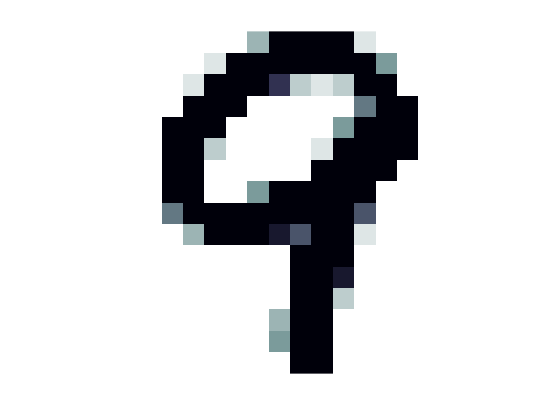

% printar ut procent för hur korrekt algoritmen var jämfört med facit
%PDif = results / testAns' * 100


r9 = [];
facit9 = [];
dummy9 = 1;
r8 = [];
facit8 = [];
dummy8 = 1;
r7 = [];
facit7 = [];
dummy7 = 1;
r6 = [];
facit6 = [];
dummy6 = 1;
r5 = [];
facit5 = [];
dummy5 = 1;
r4 = [];
facit4 = [];
dummy4 = 1;
r3 = [];
facit3 = [];
dummy3 = 1;
r2 = [];
facit2 = [];
dummy2 = 1;
r1 = [];
facit1 = [];
dummy1 = 1;
r0 = [];
facit0 = [];
dummy0 = 1;

for i=1:2007
    if(testAns(i,1) == 9)
        r9(1,dummy9) = results(1,i);
        facit9(1,dummy9) = testAns(i,1);
        dummy9 = dummy9 + 1;
    end
    if(testAns(i,1) == 8)
        r8(1,dummy8) = results(1,i);
        facit8(1,dummy8) = testAns(i,1);
        dummy8 = dummy8 + 1;
    end
    if(testAns(i,1) == 7)
        r7(1,dummy7) = results(1,i);
        facit7(1,dummy7) = testAns(i,1);
        dummy7 = dummy7 + 1;
    end
    if(testAns(i,1) == 6)
        r6(1,dummy6) = results(1,i);
        facit6(1,dummy6) = testAns(i,1);
        dummy6 = dummy6 + 1;
    end
    if(testAns(i,1) == 5)
        r5(1,dummy5) = results(1,i);
        facit5(1,dummy5) = testAns(i,1);
        dummy5 = dummy5 + 1;
    end
    if(testAns(i,1) == 4)
        r4(1,dummy4) = results(1,i);
        facit4(1,dummy4) = testAns(i,1);
        dummy4 = dummy4 + 1;
    end
    if(testAns(i,1) == 3)
        r3(1,dummy3) = results(1,i);
        facit3(1,dummy3) = testAns(i,1);
        dummy3 = dummy3 + 1;
    end
    if(testAns(i,1) == 2)
        r2(1,dummy2) = results(1,i);
        facit2(1,dummy2) = testAns(i,1);
        dummy2 = dummy2 + 1;
    end
    if(testAns(i,1) == 1)
        r1(1,dummy1) = results(1,i);
        facit1(1,dummy1) = testAns(i,1);
        dummy1 = dummy1 + 1;
    end
    if(testAns(i,1) == 0)
        r0(1,dummy0) = results(1,i);
        facit0(1,dummy0) = testAns(i,1);
        dummy0 = dummy0 + 1;
    end
end

bongo = [];
dongo = 1;

for i=1:size(testAns)
    if(testAns(i,1) == 9 && results(1,i) == 9)
        bongo(:,:,dongo) = testDigits(:,:,i);
        dongo = dongo + 1;
    end
end

ima(bongo(:,:,1))
ima(bongo(:,:,2))

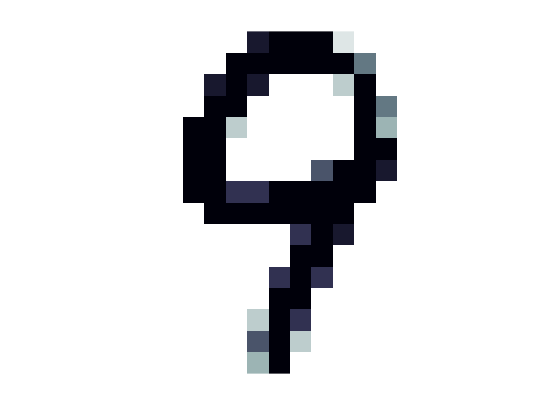

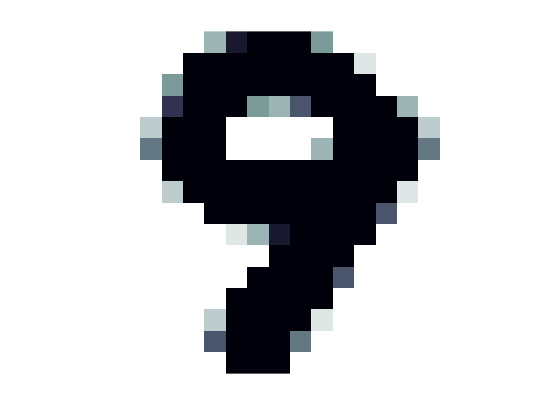

ima(bongo(:,:,3))

facit9'

ans =      9
     9
     9
     9
     9
     9
     9
     9
     9
     9


r9

r9 =      9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     7     9     9     9     9     9     9     9     9     1     7     9     9     9     9     9     7     7     9     9     1     4     9     9     9     9     9     1     9     9     9     9     9     9


PDif2 = r9 / facit9 * 100

PDif2 = 96.4218